# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.2 二维绘图

#### 2.2.5 渐变色曲线、渐变色填充

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

填充函数，fill、patch 都差不多，个人理解是填充一系列点构成的封闭区域（认为是个多边形区域也没毛病）；

**参考：**[**曲线之间填充**](https://zhuanlan.zhihu.com/p/350254385)

如果把填充颜色设置为一个变量，用来表征值的大小，也就有了渐变色填充；

单纯只想要渐变色曲线，一个大胆的想法，根据NaN不显示的特点，在原来的点集里加一个 NaN，本来封闭的区域多了一个漏点而不再封闭，整个区域的填充也就没有了，只存在一个边界，将EdgeColor设置为interp即有了渐变色效果。

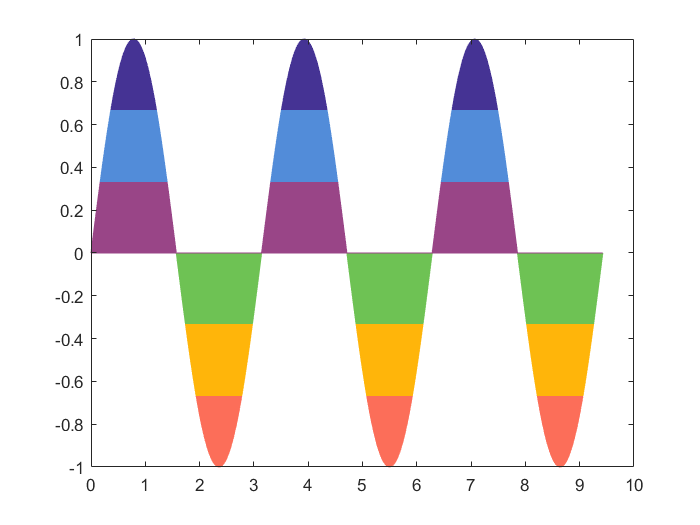

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
x = linspace(0, 3*pi, 360);
y = sin(2*x);
%%%%% 渐变色填充
figure;
fill(x, y, y, 'EdgeColor', 'interp');
colormap(all_themes{1});

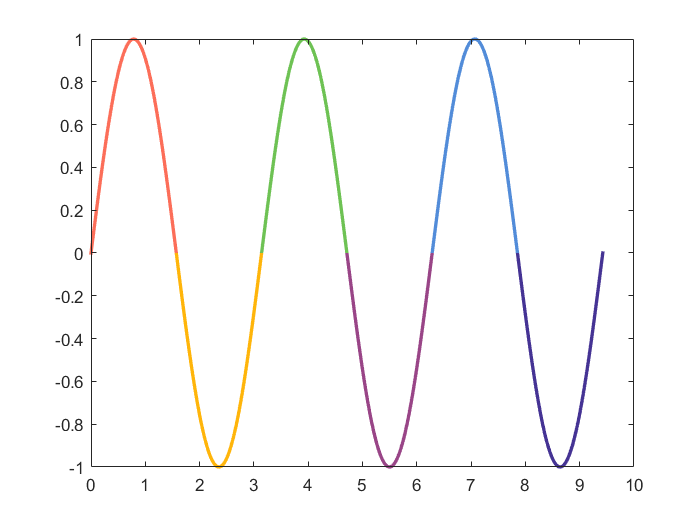

%%%%% 渐变色曲线
figure;
fill([x, NaN], [y, NaN], [x, NaN], 'EdgeColor', 'interp', 'LineWidth', 2);
% 修改颜色模板
colormap(all_themes{1});

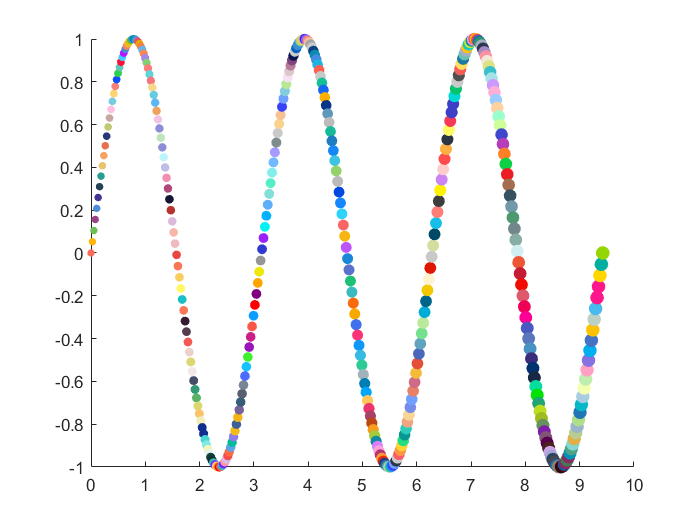

%%%%% 渐变色散点
figure;
scatter(x, y, x*5+20, x, 'filled');
colormap(all_colors);